# EE352 Automatic Control Assignment - Question 1

**Computer Aided Control Systems Analysis**

**Student Name:** Perera J.D.T.

**Registration Number:** E/21/291

**Date:** 2025/01/29

## 1. Define System Parameters

Analysis of a second order system G(s) described by:


$$G(s) = \frac{SE}{yy \cdot s^2 + mm \cdot s + dd}$$


Where the parameters are derived from the Date of Birth (2003-01-18) and Serial Number.

clc;
clear;
close all;

% Parameters
yy = 3;   
mm = 1;   
dd = 18;  
SE = 291; 

fprintf('Parameters: yy=%d, mm=%d, dd=%d, SE=%d\n', yy, mm, dd, SE);

Parameters: yy=3, mm=1, dd=18, SE=291


## Q1a: Roots and Stability

We define the denominator polynomial $D(s) = yy \cdot s^2 + mm \cdot s + dd$ and find its roots to determine individual pole locations.

Stability Condition:  If all poles have negative real parts $\rightarrow$ Stable If any pole has a positive real part $\rightarrow$ Unstable  If poles are on the imaginary axis $\rightarrow$ Marginally Stable

num = [SE];
den = [yy, mm, dd];

p = roots(den);
fprintf('\nPoles of the system:\n');


Poles of the system:


disp(p);

  -0.1667 + 2.4438i
  -0.1667 - 2.4438i




% Check Stability
if all(real(p) < 0)
    disp('Result: The system is STABLE.');
elseif any(real(p) > 0)
    disp('Result: The system is UNSTABLE.');
else
    disp('Result: The system is MARGINALLY STABLE.');
end

Result: The system is STABLE.


## Q1b: Transfer Function and Pole-Zero Plot

We create the Transfer Function object G(s) and plot the pole-zero map.

G = tf(num, den);
disp('Transfer Function G(s):');

Transfer Function G(s):


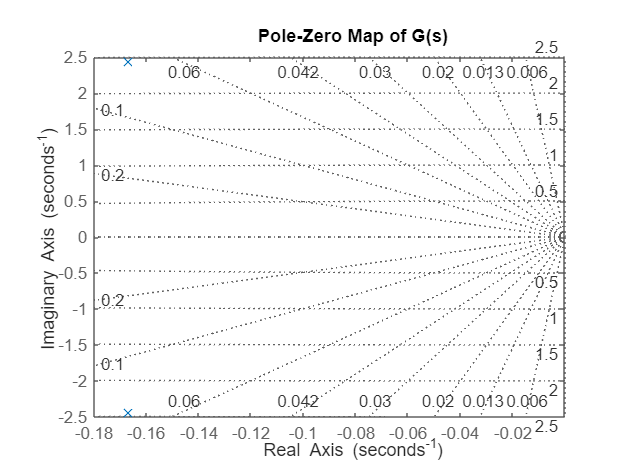



figure('Name', 'Q1b: Pole-Zero Map');
pzmap(G);
title('Pole-Zero Map of G(s)');
grid on;

## Q1c: Step Response

The step response shows the system's output behavior when the input changes from 0 to 1 instantaneously.

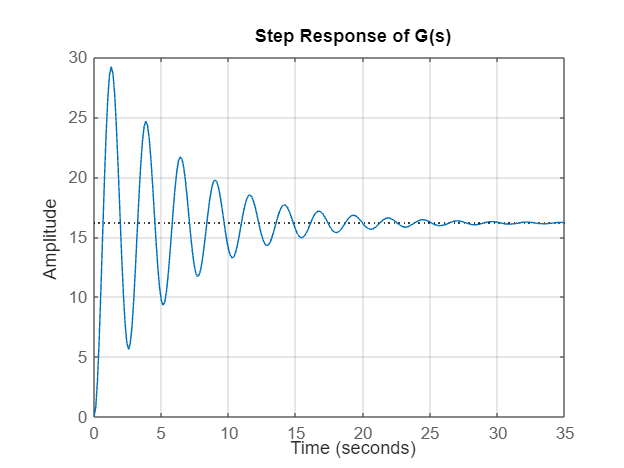

figure('Name', 'Q1c: Step Response');
step(G);
title('Step Response of G(s)');
grid on;

## Q1d: State Space Representation

We convert the Transfer Function to a State Space representation:


$$ \dot{x} = Ax + Bu $$


$$ y = Cx + Du $$


We then verify the conversion by plotting the step response of the state space model.

sys_ss = ss(G);
disp('State Space Model:');

State Space Model:


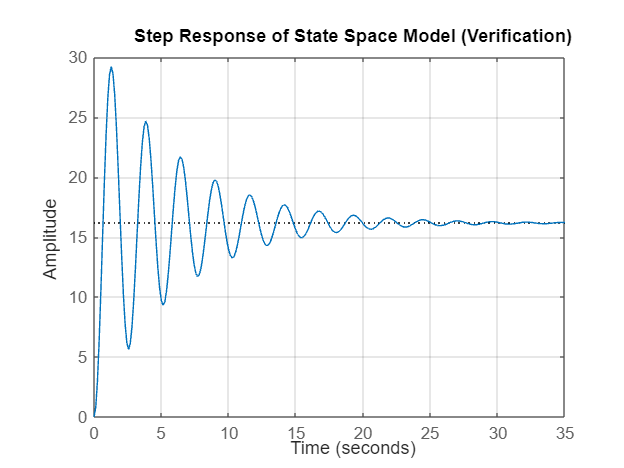



figure('Name', 'Q1d: State Space Verification');
step(sys_ss);
title('Step Response of State Space Model (Verification)');
grid on;